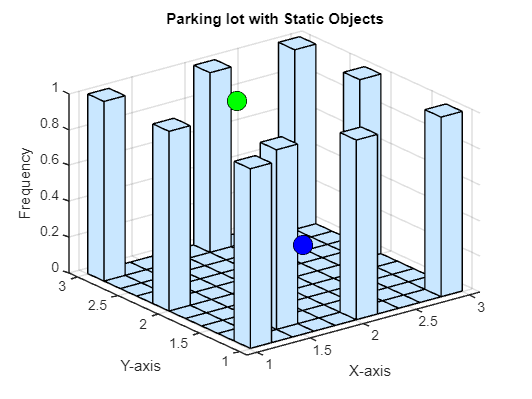

x = [1 1; 1 2; 1 3; 2 1; 1.5 1.25; 2 3; 3 1; 3 2; 3 3];
hist3(x);

% Set up the axes
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Frequency');
title('Parking lot with Static Objects');

% Define positions for static objects
staticObjects = [1.5 1.5 0.5; 2.5 2.5 0.5; 1.5 2.5 0.5; 2.5 1.5 0.5]; % Add more objects as needed

% Define positions for anchors (LOS and NLOS)
LOS_anchor = [1.8, 2.2, 1.0];  % LOS anchor
NLOS_anchor = [1.5, 1, 0.5]; % NLOS anchor

% Plot static objects
hold on;
scatter3(staticObjects(:, 1), staticObjects(:, 2), staticObjects(:, 3), 100, 'filled', 'MarkerFaceColor', 'r');

% Plot anchors
scatter3(LOS_anchor(1), LOS_anchor(2), LOS_anchor(3), 200, 'filled', 'MarkerFaceColor', 'g', 'MarkerEdgeColor', 'k'); % LOS anchor
scatter3(NLOS_anchor(1), NLOS_anchor(2), NLOS_anchor(3), 200, 'filled', 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'k'); % NLOS anchor

hold off;



% MAC layer:
payload = '00'; 
cfg = lrwpan.MACFrameConfig( ...
        FrameType='Data', ...
        SourceAddressing='Short address', ...
        SourcePANIdentifier='AB12', ...
        SourceAddress='CD77');
blinkMAC = lrwpan.MACFrameGenerator(cfg,payload);

% PHY layer:
% Ensure the Ranging field is enabled. 
% Also set the proper PSDU length.
blinkPHYConfig = lrwpanHRPConfig( ...
    Mode='HPRF', ...
    STSPacketConfiguration=1, ...
    PSDULength=length(blinkMAC)/8, ...
    Ranging=true);
blinkPHY = lrwpanWaveformGenerator( ...
    blinkMAC, ...
    blinkPHYConfig);

% Cache preamble, to use in preamble detection. 
% Get the 1st instance out of the Nsync=PreambleDuration repetitions.
indices = lrwpanHRPFieldIndices(blinkPHYConfig); % length (start/end) of each field
blinkPreamble = blinkPHY( ...
    1:indices.SYNC(end)/blinkPHYConfig.PreambleDuration); % 1 of the Nsync repetitions

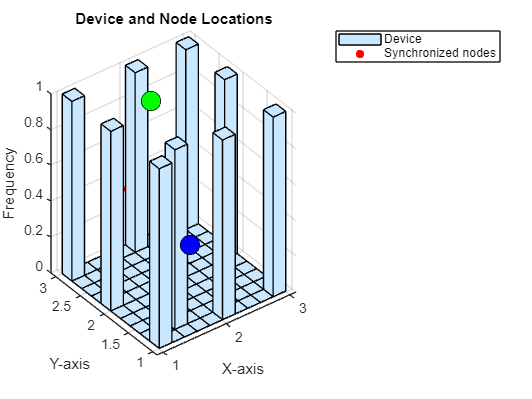

% UWB Localization Using IEEE 802.15.4z

% Configure Network
numNodes = 3;
deviceLoc = [50 50];  % place device at the center
nodeLoc = [40 41;
           62 83;
           87 24];
TDOA = nan(numNodes);

% Call the function to visualize device and node locations
visualizeLocations(deviceLoc, nodeLoc);


% Calculate the actual distance and time of flight (TOF) between nodes and the device.
actualDistances = sqrt(sum((nodeLoc - deviceLoc).^2, 2));
c = physconst('LightSpeed'); % speed of light (m/s)
actualTOF = actualDistances/c;

SNR = 30;  % in dB sound to noise ratio

% Configure Blinks
numBlinks = 1;

payload = '00'; 
cfg = lrwpan.MACFrameConfig( ...
        'FrameType','Data', ...
        'SourceAddressing','Short address', ...
        'SourcePANIdentifier','AB12', ...
        'SourceAddress','CD77');
blinkMAC = lrwpan.MACFrameGenerator(cfg,payload);

blinkPHYConfig = lrwpanHRPConfig( ...
    'Mode','HPRF', ...
    'STSPacketConfiguration',1, ...
    'PSDULength',length(blinkMAC)/8, ...
    'Ranging',true);
blinkPHY = lrwpanWaveformGenerator( ...
    blinkMAC, ...
    blinkPHYConfig);

indices = lrwpanHRPFieldIndices(blinkPHYConfig); % length (start/end) of each field
blinkPreamble = blinkPHY( ...
    1:indices.SYNC(end)/blinkPHYConfig.PreambleDuration); % 1 of the Nsync repetitions

% Run Simulation
tic; % Start measuring time

vfd = dsp.VariableFractionalDelay;
arrivalTime = zeros(1,numNodes);

plotStr = {'r--','b--','g--'};
[x, y] = deal(cell(1, 3));

for idx = 1:numBlinks
  for node = 1:numNodes
    tof = actualTOF(node);
    samplesToDelay = tof * blinkPHYConfig.SampleRate;
    reset(vfd);
    release(vfd);
    vfd.MaximumDelay = ceil(1.1*samplesToDelay);
    delayedBlink = vfd( ...
        [blinkPHY; zeros(ceil(samplesToDelay), 1)], ...
        samplesToDelay);

    receivedBlink = awgn(delayedBlink,SNR);

    preamPos = helperFindFirstHRPPreamble( ...
        receivedBlink,blinkPreamble,blinkPHYConfig);
 
    arrivalTime(node) = ( ...
        preamPos - indices.SYNC(end) / ...
        blinkPHYConfig.PreambleDuration)/blinkPHYConfig.SampleRate;
  end

  pairCnt = 1;
  for node1 = 1:numNodes
    for node2 = (node1+1):numNodes
      TDOA(node1, node2) = arrivalTime(node1)-arrivalTime(node2);
      
      [x{pairCnt}, y{pairCnt}] = helperGetHyperbolicSurface( ...
          nodeLoc(node1,:), ...
          nodeLoc(node2,:), ...
          TDOA(node1,node2));

      plot(x{pairCnt},y{pairCnt},plotStr{pairCnt});
      pairCnt = pairCnt + 1;
    end
  end
  
  [xC,yC] = helperFindHyperbolicIntersection(x,y);
  xO = mean(xC, 2);
  yO = mean(yC, 2);

  plot(xO, yO, 'ro')
  plot(xC',yC','rx')
end

'helperFindFirstHRPPreamble' is used in the following examples:
  UWB Localization Using IEEE 802.15.4z
  UWB Ranging Using IEEE 802.15.4z


% Print time taken
elapsedTime = toc; % Time taken for the simulation
fprintf('Time taken for simulation: %0.3f seconds.\n', elapsedTime);

% Calculate localization error for each estimated position
for idx = 1:numel(xO)
    locError = sqrt(sum(([xO(idx), yO(idx)] - deviceLoc).^2));
    fprintf('Localization error #%d = %0.3f m.\n', idx, locError);
end

leg = legend( ...
    'Device', ...
    'Synchronized nodes', ...
    'A-B', ...
    'A-C', ...
    'B-C', ...
    'Estimation', ...
    'Intersections', ...
    'location','northwest');

zoomInToEstimationArea(deviceLoc,xC,yC,xO,yO,leg);

function visualizeLocations(deviceLoc, nodeLoc)
    hold on;
    scatter(deviceLoc(1), deviceLoc(2), 200, 'filled', 'MarkerFaceColor', 'm', 'MarkerEdgeColor', 'k'); % Device
    scatter(nodeLoc(:, 1), nodeLoc(:, 2), 200, 'filled', 'MarkerFaceColor', 'c', 'MarkerEdgeColor', 'k'); % Nodes
    hold off;
    legend('Device', 'Synchronized nodes');
    xlabel('X-axis');
    ylabel('Y-axis');
    title('Device and Node Locations');
    grid on;
end

function zoomInToEstimationArea(deviceLoc,xC,yC,xO,yO,leg)
  allX = [deviceLoc(1); xO(:); xC(:)];
  allY = [deviceLoc(2); yO(:); yC(:)];
  minX = min(allX);
  maxX  = max(allX);
  minY = min(allY);
  maxY = max(allY);
  axis([ ...
      minX-0.1*(maxX-minX), ...
      maxX+0.1*(maxX-minX), ...
      minY-0.1*(maxY-minY), ...
      maxY+0.1*(maxY-minY)])
  leg.Location = 'NorthEast';
end

% Print time taken
elapsedTime = toc; % Time taken for the simulation
fprintf('Time taken for simulation: %0.3f seconds.\n', elapsedTime);

% Calculate localization error for each estimated position
for idx = 1:numel(xO)
    locError = sqrt(sum(([xO(idx), yO(idx)] - deviceLoc).^2));
    fprintf('Localization error #%d = %0.3f m.\n', idx, locError);
end
